# Marginal cost data analysis

## Load marginal cost data

% You have to run this under model_code directory
MCFileDir = "../model_output/";
MCFileName = "MC_*.csv";
MCDataStore = fileDatastore(MCFileDir + MCFileName, "ReadFcn", @importMarginalCost, "UniformRead", true);
MCAll = readall(MCDataStore);
clear MCDataStore;

numTopParts = 10;
rankedParts = sortrows(groupsummary(MCAll, "PartID"), "GroupCount", "descend");
topPartIDs = rankedParts.PartID(1:numTopParts);

topPartQMCTables = cell(size(topPartIDs));
for n = 1:size(topPartIDs, 1)
    topPartQMCTables{n} = MCAll(MCAll.PartID == topPartIDs(n), :);
end

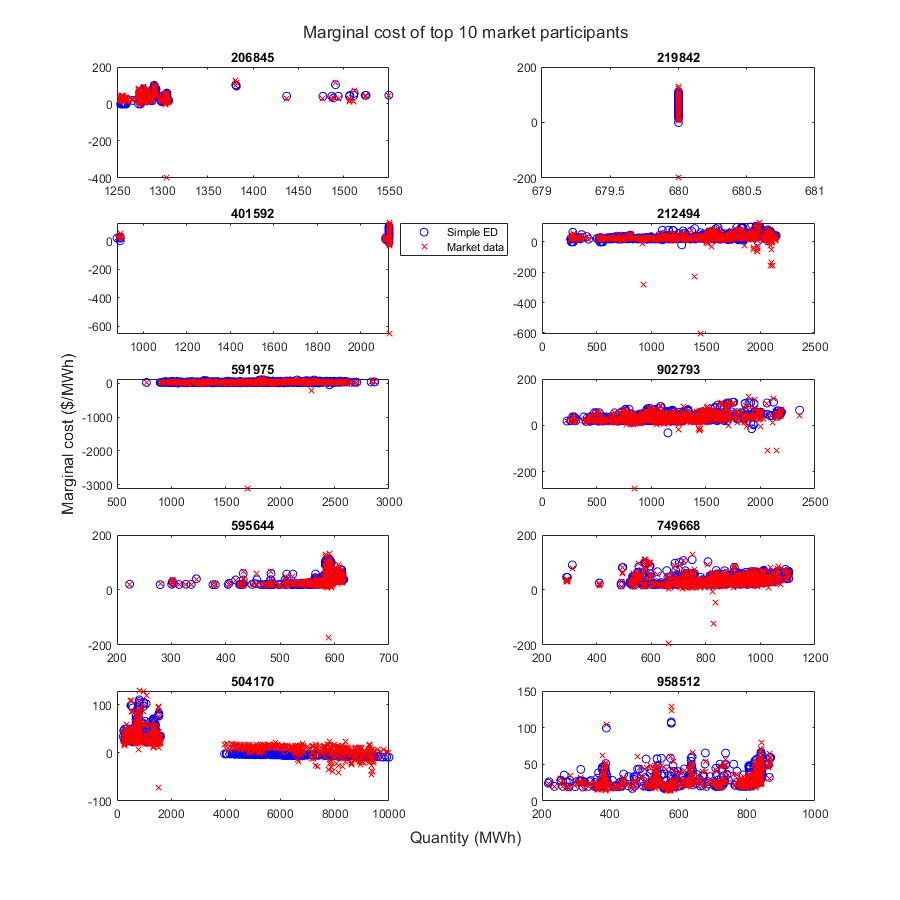

t = tiledlayout(numTopParts/2, 2, "TileSpacing","compact");
for n = 1:size(topPartIDs, 1)
    nexttile;
    partQMCTable = topPartQMCTables{n};
    partID = topPartIDs(n);
    scatter(partQMCTable.Awarded, partQMCTable.MCSimpleED, 'bo');
    hold on;
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    if n==3
        legend(["Simple ED", "Market data"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Marginal cost of top 10 market participants");

set(gcf, "Position", [100, 100, 900, 900]);

## Fit polynomial relation between marginal cost and quantity

% polyOrder = 2;
% topPartMCPoly = zeros(numTopParts, polyOrder);
% for n = 1:size(topPartIDs, 1)
%     partQMCTable = topPartQMCTables{n};
%     partID = topPartIDs(n);
%     MCPoly = polyfit(partQMCTable.Awarded, partQMCTable.MCSimpleED, polyOrder);
%     topPartMCPoly(n, :) = MCPoly;
% end
% topPartMCPoly